**Testing Notebook**

**Kuan-Min Lee**

**Purpose of creating this notebook:**

This notebook is created for intension of testing .m script file of different functions.

**img_spatio_freq.m function:**

**Testing of sinusodial signal in one direction (horizontal):**

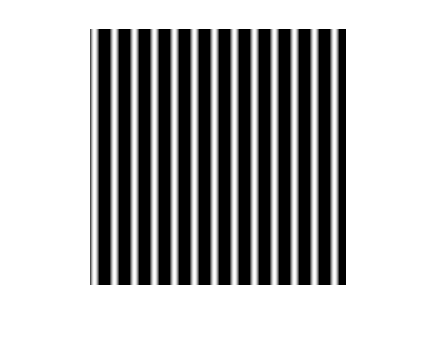

% create 2D sinusoid image
img_size=256; % create an image with size of 256 
lambda=20; % create pattern with wavelength
k=2*pi/lambda; % define k number
x=1:img_size; % setup x range
I=sin(1*k*x); % setup sinusoid signal
sin_2d=repmat(I,img_size,1);
imshow(sin_2d)

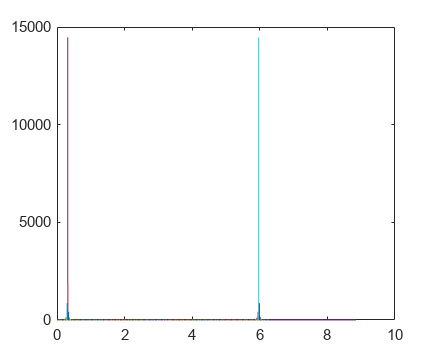

common_freq =          0    0.3191


maximum_freq =          0    6.2586


minimum_freq =      0     0


[common_freq,maximum_freq,minimum_freq]=img_spatio_freq(sin_2d)

% convert the frequency into wavelength
common_wave=freq_wave_converter(sin_2d,common_freq);

factor_wav = 4;
factor_angle = 3;
[opt_wave, opt_angle]=optimal_wave_angle(sin_2d, factor_wav, factor_angle);


    % conduct gabor filtering
    if size(image,3)~= 1
        gray_img=rgb2gray(image);
    else
        gray_img=image;
    end
    % create gabor filters
    g = gabor(opt_wav,opt_angle);
    [mag_gabor,phase_gabor]=imgaborfilt(gray_img,g);
    montage(mag_gabor,"size",[4 6])


**Testing of sinusoidal signal in one direction (vertical direction):**

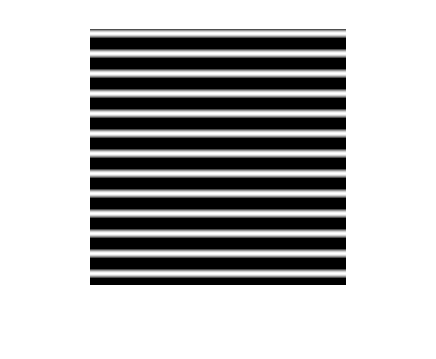

% create 2D sinusoid image
img_size=256; % create an image with size of 256 
lambda=20; % create pattern with wavelength
k=2*pi/lambda; % define k number
x=1:img_size; % setup x range
I=sin(1*k*x); % setup sinusoid signal
I=transpose(I);
sin_2d_x=repmat(I,1,img_size);
imshow(sin_2d_x)

[common_freq_x,maximum_freq_x,minimum_freq_x]=img_spatio_freq(sin_2d_x) % convert the frequency into wavelength

% convert the frequency into wavelength
common_wave_x=freq_wave_converter(sin_2d_x,common_freq_x);

**Testing on sinusodial signal in two direction (both vertical and horizontal directions):**

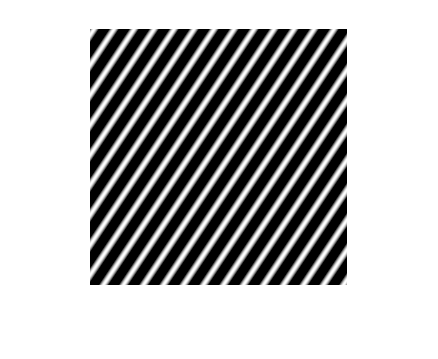

% create 2D sinusoid image
img_size=256; % create an image with size of 256 
lambda_x=20; % create pattern for x
lambda_y=30; % create pattern for y
kx=2*pi/lambda_x; % define kx number
ky=2*pi/lambda_y; % define ky number
x=1:img_size; % setup x range
y=1:img_size+1; % setup y range
[gx,gy]=ndgrid(x,y); % setup grid values
I=sin(1*kx*gy+1*ky*gx); % setup sinusoid signal
sin_2d_both=I;
imshow(sin_2d_both)

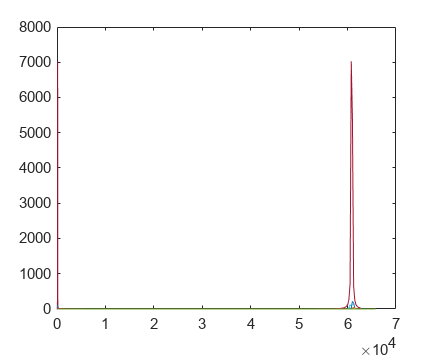

common_freq_both =     0.2209    0.3178


maximum_freq_both =     6.2586    6.2587


minimum_freq_both =      0     0


[common_freq_both,maximum_freq_both,minimum_freq_both]=img_spatio_freq(sin_2d_both) % convert the frequency into wavelength

% convert the frequency into wavelength
common_wave_x_2=freq_wave_converter(sin_2d_both,common_freq_both);